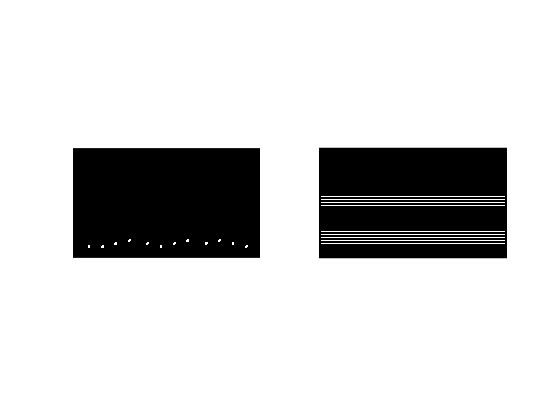

I = imread("Test Images/music2.jpg");

I_gray = rgb2gray(I); % convert to greyscale
I_bin = imbinarize(I_gray); % threshold convert to binary image
I_inv = imcomplement(I_bin); % invert image so background is false & print is true

[M,N] = size(I_bin);

stave_SE = strel('line',25,0); % create line structuring element to find staves
I_stave = imopen(I_inv,stave_SE); % erode then dilate to isolate staves

% find the vertical coordinates of each stave line
stave = 1;
line = 1;
dif_line = true;
for i = 1:M
    % record coordinate if new stave line is detected
    if I_stave(i,round(N/2)) && dif_line
        stave_coords(stave,line) = i;
        dif_line = false;
        if line >= 5
            line = 1;
            stave = stave + 1;
        else
            line = line + 1;
        end
    % reset dif_line flag after each stave line detection
    elseif ~I_stave(i,round(N/2))
        dif_line = true;
    end
end

% calculate average distance between stave lines
line_dist = 0;
[num_staves,x] = size(stave_coords);
for i = 1:num_staves
    for j = 1:4
        line_dist = line_dist + stave_coords(i,j+1) - stave_coords(i,j);
    end
end
line_dist = line_dist / (4*num_staves);

% deterine note value thresholds
for i = 1:num_staves
    note_threshs(i,:) = [(stave_coords(i,1)-1.25*line_dist):(line_dist/2):(stave_coords(i,5)+0.25*line_dist)];
end

% compute stave bounds
stave_bounds = zeros(num_staves,4);
for i = 1:num_staves
    stave_bounds(i,1) = stave_coords(i,1);
    stave_bounds(i,2) = stave_coords(i,5);
    for j = round(N/2):-1:1
        if ~I_stave(stave_coords(i,1),j)
            stave_bounds(i,3) = j;
            break
        end
    end
    for j = round(N/2):N
        if ~I_stave(stave_coords(i,1),j)
            stave_bounds(i,4) = j;
            break
        end
    end
end

% compute possible note bounds
note_bounds = stave_bounds;
for i = 1:num_staves
    note_bounds(i,2) = note_bounds(i,2) + 20;
    note_bounds(i,3) = note_bounds(i,3) + 24;
end

note_SE = strel('disk',3); % create disk structuring element to find notes
note_coords = [];
for i = 1:num_staves
    % remove all data outside possible note areas for note detection
    mask_notes_pre = zeros(M,N,'logical');
    mask_notes_pre(note_bounds(i,1):note_bounds(i,2),note_bounds(i,3):note_bounds(i,4)) = true;
    I_notes_pre = I_inv & mask_notes_pre;
    
    % erode then dilate to isolate notes
    I_notes = imopen(I_notes_pre,note_SE);
    
    % find note coordinates
    note_stats = regionprops('table',I_notes,'Centroid');
    note_coords = [note_coords;note_stats.Centroid];
end

% determine note values


figure
subplot(1,2,1), imshow(I_notes)
subplot(1,2,2), imshow(I_stave)